## State-space model

#### Random open-loop state-space model

We create a random STABLE state space model of dimension 10, with 5 inputs and 10 outputs. In order to do it we create a function that makes sure that the matrix A is negative definite, and that also generates B, C and D according to the given dimensions. Since we want to create both a controller and an observer for our system we make sure that it is both reachable and observable, if not we create a new model.

% Set the seed of the random number generator
rng(123);

% dimensions of the state-space model
n = 10; % number of states
m = 5; % number of inputs
p = 10; % number of outputs 

% random matrices for the a stable open-loop state-space model
[A,B,C,D] = createsys(n,m,p);

% Compute the reachability and the observability matrices and their rank
R = ctrb(A,B);
rank_R = rank(R);
O = obsv(A,C);
rank_O = rank(O);
% Check if the system is both reachable and observable, if not create a new one
while or(rank_R ~= n, rank_O ~= n)
    [A,B,C,D] = createsys(n,m,p) 
    R = ctrb(A, B);
    rank_R = rank(R);
    O = obsv(A,C);
    rank_O = rank(O);
end
% Display the rank of the reachability matrix
disp('Rank of controllability matrix:');

Rank of controllability matrix:


disp(rank_R);

    10



% Display the rank of the observability matrix
disp('Rank of observability matrix:');

Rank of observability matrix:


disp(rank_O);

    10



%eigenvalues of the matrix of the open-loop system 
lambdas = eig(A);
% Display the eigenvalues of A
disp('Eigenvalues of A:');

Eigenvalues of A:


disp(lambdas);

   -3.4132
   -3.4554
   -2.5111
   -1.7499
   -0.2459
   -0.3864
   -1.4590
   -1.2632
   -0.8373
   -0.8343



%check if the open-loop system is stable
if all(lambdas < 0)
    disp('The open-loop system is stable');
else 
    disp('The open-loop system is unstable');
end

The open-loop system is stable


% state-space model object
sys = ss(A,B,C,D);

#### Proportional controller Kp

We perform state feedback control by setting: u = -Kx_hat + v. Through the feedback matrix K we can place the eigenvalues of the closed-loop state space model at the desired values. In particular we set the desired eigenvalues to be random negative values (so that we have stability of the closed-loop system) and we compute the matrix K by exploiting the Matlab method "place".

% Define the desired closed-loop poles (normally distributed random negative values)
lambda_des =-abs(randn(n,1));

% Calculate the controller gain using the pole-placement technique
Kp = place(A, B, lambda_des);

% Display the controller gain
disp('Controller Gain Kp:');

Controller Gain Kp:


disp(Kp);

   -0.7361    0.7644    0.0799   -0.2348   -0.9505    0.5325   -0.7428    0.2996    0.3037    0.0542
    0.1351   -1.0198    0.0786   -1.0793    0.5178   -1.3843    0.5773    1.7193    1.7355    0.2029
   -0.4536    0.1694    0.1856    0.0944   -1.0247    0.6008   -0.3237    0.1372   -0.3366    0.1486
   -0.3328    0.0664    0.0097    0.2577   -0.0805   -0.1067   -0.1964    0.2974    0.1337   -0.0035
    0.1562   -0.2349    0.0941    0.3088   -0.3960   -0.2196    0.1985    0.0739   -0.4640    0.0761



#### Stable closed-loop state-space model

The closed-loop system will have as state matrix the matrix: A - B*Kp (separation principle).

%matrices of the closed-loop system 
A_c = A - B * Kp;
B_c = B;
C_c = C;
D_c = D;

% Display the eigenvalues of A_c
lambdas_c = eig(A_c);
disp('Eigenvalues of A_c:');

Eigenvalues of A_c:


disp(lambdas_c);

   -2.0146
   -1.1962
   -0.9143
   -0.0722
   -0.1487
   -0.1148
   -0.7607
   -0.5396
   -0.4543
   -0.4996




% state-space model object
sys_c = ss(A_c,B_c,C_c,D_c);

%check if the eigenvalues of the closed-loop system are the desired ones
lambdas_c = sort(lambdas_c);
lambda_des = sort(lambda_des);
epsilon = 1e-10; 
if abs(lambda_des-lambdas_c) < epsilon
    disp('We obtained the desired eigenvalues for the closed-loop system');
end

We obtained the desired eigenvalues for the closed-loop system


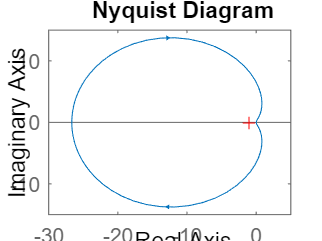

W_1 = tf(sys_c);
nyquist(sys_c(3,3))

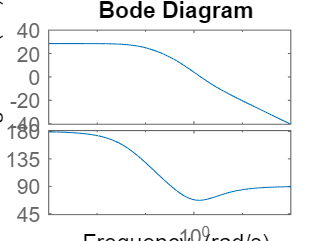

bode(sys_c(3, 3))

#### State observer L

We compute a full-order closed-loop observer, that will output an estimate of the state of the system. The state-space equation of the observer system is x_hat_dot =  Ax_hat+Bu+L(y-y_hat)=

=(A-LC)x_hat+Ly+(B-LD)u.

% dimensions of the observer
n_o = n; % number of states
m_o = m + p; % number of inputs
p_o = p; % number of outputs 

% Define the desired observer poles
lambda_des_o = -abs(randn(n,1)) - max(abs(lambdas));
% Calculate the observer gain using the pole-placement technique on the dual system
L = place(A',C',lambda_des_o)'; 
% Display the observer gain
disp('Observer Gain L:');

Observer Gain L:


disp(L);

    2.3497    0.4473    0.1131    0.1699   -0.4055    0.4711   -0.7111    0.5598    0.1955    0.1069
    0.4473    2.7516   -0.1194    0.0564    0.3774   -0.2538    0.6257    0.4074   -0.0236    0.1578
    0.1131   -0.1194    2.5444    0.0130    0.2370   -0.0108   -0.0537   -0.2354    0.0655   -0.2874
    0.1699    0.0564    0.0130    2.0920   -0.0301   -0.1458    0.2701    0.3853    0.8029    0.1447
   -0.4055    0.3774    0.2370   -0.0301    1.7362    0.1183   -0.1969    0.5867   -0.2775    0.1623
    0.4711   -0.2538   -0.0108   -0.1458    0.1183    1.8229    0.5398    0.5788    0.1343    0.0690
   -0.7111    0.6257   -0.0537    0.2701   -0.1969    0.5398    2.7203   -0.1160    0.3741    0.1100
    0.5598    0.4074   -0.2354    0.3853    0.5867    0.5788   -0.1160    3.2969   -0.7588   -0.2305
    0.1955   -0.0236    0.0655    0.8029   -0.2775    0.1343    0.3741   -0.7588    2.1854    0.0499
    0.1069    0.1578   -0.2874    0.1447    0.1623    0.0690    0.1100   -0.2305    0.0499 

% matrices of the observer
A_o = A - L*C;
B_o = [B-L*D,L];
C_o = C;
D_o = zeros(p_o,m_o);
% Display the eigenvalues of A_o
lambdas_o = eig(A_o);
disp('Eigenvalues of A_o:');

Eigenvalues of A_o:


disp(lambdas_o);

   -5.0431
   -4.5784
   -4.4009
   -4.1823
   -4.1774
   -3.9829
   -3.9117
   -3.7605
   -3.7345
   -3.6420



%check if the eigenvalues of the observer are the desired ones
lambdas_o = sort(lambdas_o);
lambda_des_o = sort(lambda_des_o);
epsilon = 1e-10; 
if abs(lambda_des_o-lambdas_o) < epsilon
    disp('We obtained the desired eigenvalues for the observer');
end

We obtained the desired eigenvalues for the observer


% observer
sys_o = ss(A_o,B_o,C_o,D_o);

#### Residual

The state-space equation of the residual error r = x-x_hat is e_dot = (A-LC)e + Bd

%matrices of the error system 
A_r = A - L * C;
B_r = B;
C_r = C;
D_r = D;
eigenvaluesAr = eig(A_r);
mu = max(eigenvaluesAr);
% state-space model object
sys_r = ss(A_r,B_r,C_r,D_r);

#### Threshold

To obtain the threshold to be used for the generation of the residual we compute the 1-norm of the impulse response of the system and we multiply it by the maximum value of the disturbance input so that we obtain the maximum value for the output when subject to the disturbance, which is exactly the threshold. Therefore, if the measured output is greater than this value (that means something is wrong since this value is the maximum we are expecting even in the case in which the disturbance is the highest) we will generate an alarm signal.

%transfer function and impulse response of the closed-loop system
W = tf(sys_r);
[w,t_w] = impulse(sys_r);
%1-norm of the closed-loop system
w = abs(w);
integrall = trapz(w);
integrall = permute(integrall,[3,2,1]);
norm1_W = max(integrall)';
%2-norm of the closed-loop system
norm2_W = norm(W, 2);
%infinite-norm of the closed-loop system
norminf_W = norm(W, Inf);
%infinite-norm of the disturbance signal
d_bar = 0.2;
%threshold on the infinite norm of the output based on the 1-norm of the
%system and the infinite-norm of the input disturbance
threshold = norm1_W*d_bar;
disp('Threshold:');

Threshold:


disp(threshold);

    9.1330
    6.4767
    3.9756
    5.7619
    3.3093
    3.9199
    5.5032
    3.8582
    3.4928
    4.8842



#### System discretization

% Discretize the system using the forward Euler method
Ts = 0.01; % Sampling time
sys_d = c2d(sys, Ts, 'zoh');
sys_o_d = c2d(sys_o, Ts, 'zoh');
sys_r_d = c2d(sys_r, Ts, 'zoh');

## Replay attack

In the replay attack, at a random time t1 the attacker starts recording the output y of the system for a time window of a certain length (we will consider attacks of 5,10,20,50,100 time stamps). Then at another time instant t2>(t1+w_length) the attacker substitutes the real ouput of the system during a time window of the same duration as the previous one, with the sequence previously recorded.

%we set this variable to true if we want to simulate the replay attack
attack = true;
thresh1 = false;
delta = 5;
w_length = 2; %w_length is the length of the attack that we will implement later on
%T_simulation = 10*w_length; %we set the simulation time
T_simulation = 20;
N = T_simulation/Ts; % Number of time steps (0 is not counted because I don't include it in the for loop)
%time vector: equally spaced between 0 and T_simulation with Ts = 0.01
t = (0:N)*Ts;
%and a random time instant where we start copying the previous sequence
%instead of the true one
%t2 = randi([t1+w_length+1,T_simulation-w_length]);
k2 = randi([w_length/Ts+1,N-w_length/Ts-1]);
t2 = k2*Ts;
%we select a random time instant to start recording the output
%t1 = randi([0,T_simulation-2*w_length-1]);
k1 = randi([max(0,k2-delta/Ts),k2-w_length/Ts-1]);
t1 = k1*Ts;
y_attack = zeros(n, w_length/Ts+1);

x = zeros(n, 1); % Initialize the state vector of the open loop
x_hat = x; % Initialize the predicted state vector of the observer

%Initialize the input disturbance
d = -0.2 + (0.2+0.2)*rand(m,1); %random offset of the sine (each component of the disturbance has a different offset)
dmax = 0.2;
infnormB = norm(B, Inf);
v = zeros(m,1); %at the beginning t = 0 and hence the sine is 0;
u = v - Kp*x_hat; 
y = sys_d.C*x + sys_d.D*(u+d); %measured output
y_bar = y; %corrupted output
y_hat = sys_o_d.C*x_hat + sys_o_d.D*[u;y_bar];
r = abs(y_bar - y_hat);
%indices 
i = 0;
j = 0;
if attack && k1 == 0
    i = i+1;
    y_attack(:,1) = y;
end
output = zeros(n, N+1); % Initialize the output matrix to store the output values
output(:,1) = y;
corrupted_output = zeros(n, N+1);
corrupted_output(:,1) = y_bar;
estimated_output = zeros(n, N+1);
estimated_output(:,1) = y_hat;
residual = zeros(n, N+1);
residual(:,1) = r;
alarm = zeros(N+1,1);
expo = @(tau) exp(mu*(-tau));
threshold1 = zeros(N+1,1);
threshold1(1) = infnormB * dmax * integral(expo, 0, 0);

for k = 1:N
    x = sys_d.A*x + sys_d.B*(u+d); % Update the state at time k+1
    x_hat = sys_o_d.A*x_hat + sys_o_d.B*[u;y_bar];
    %I set the frequency of the disturbance and the disturbance itself
    omega = 9/(5e4)*k*Ts+1;
    v = sin(omega*k*Ts)*ones(m,1);
    u = v - Kp*x_hat; 
    y = sys_d.C*x + sys_d.D*(u+d);
    if attack && (k >= k2) && (k <= k2+w_length/Ts)
        j = j+1;
        y_bar = y_attack(:,j);
    else
        y_bar = y;
    end
    y_hat = sys_o_d.C*x_hat + sys_o_d.D*[u;y_bar];
    r = abs(y_bar - y_hat);
    expo = @(tau) exp(mu*(Ts*k-tau));
    threshold1(k+1) = infnormB*dmax*integral(expo,0,Ts*k);
    cond = (r > threshold);
    if thresh1 == true && any(cond)
        alarm(k+1) = 1;
    end
    cond2 = r > ones(p,1)*threshold1(k+1);
    if thresh1 == false && any(cond2)
        alarm(k+1) = 1;
    end
    %if we are in the time window starting from t1 we record the ouput
    if attack && (k >= k1) && (k <= k1+w_length/Ts)
        i = i+1;
        y_attack(:,i) = y;
    end
    %I store in 2 matrices the output and the disturbance of the system at all the time instants
    output(:,k+1) = y;
    estimated_output(:,k+1) = y_hat;
    corrupted_output(:,k+1) = y_bar;
    residual(:,k+1) = r;
end

## To avoid running the code multiple times

for i = 1:50  %number of simulations
    %we set this variable to true if we want to simulate the replay attack
    attack = true;
    thresh1 = false;
    w_length = 2; %w_length is the length of the attack that we will implement later on
    %T_simulation = 10*w_length; %we set the simulation time
    T_simulation = 20;
    N = T_simulation/Ts; % Number of time steps (0 is not counted because I don't include it in the for loop)
    %time vector: equally spaced between 0 and T_simulation with Ts = 0.01
    t = (0:N)*Ts;
    %and a random time instant where we start copying the previous sequence
    %instead of the true one
    %t2 = randi([t1+w_length+1,T_simulation-w_length]);
    k2 = randi([w_length/Ts+1,N-w_length/Ts-1]);
    t2 = k2*Ts;
    %we select a random time instant to start recording the output
    %t1 = randi([0,T_simulation-2*w_length-1]);
    k1 = randi([max(0,k2-delta/Ts),k2-w_length/Ts-1]);
    t1 = k1*Ts;
    y_attack = zeros(n, w_length/Ts+1);
    
    x = zeros(n, 1); % Initialize the state vector of the open loop
    x_hat = x; % Initialize the predicted state vector of the observer
    
    %Initialize the input disturbance
    d = -0.2 + (0.2+0.2)*rand(m,1); %random offset of the sine (each component of the disturbance has a different offset)
    dmax = 0.2;
    infnormB = norm(B, Inf);
    v = zeros(m,1); %at the beginning t = 0 and hence the sine is 0;
    u = v - Kp*x_hat; 
    y = sys_d.C*x + sys_d.D*(u+d); %measured output
    y_bar = y; %corrupted output
    y_hat = sys_o_d.C*x_hat + sys_o_d.D*[u;y_bar];
    r = abs(y_bar - y_hat);
    %indices 
    i = 0;
    j = 0;
    if attack && k1 == 0
        i = i+1;
        y_attack(:,1) = y;
    end
    output = zeros(n, N+1); % Initialize the output matrix to store the output values
    output(:,1) = y;
    corrupted_output = zeros(n, N+1);
    corrupted_output(:,1) = y_bar;
    estimated_output = zeros(n, N+1);
    estimated_output(:,1) = y_hat;
    residual = zeros(n, N+1);
    residual(:,1) = r;
    alarm = zeros(N+1,1);
    expo = @(tau) exp(mu*(-tau));
    threshold1 = zeros(N+1,1);
    threshold1(1) = infnormB * dmax * integral(expo, 0, 0);
    
    for k = 1:N
        x = sys_d.A*x + sys_d.B*(u+d); % Update the state at time k+1
        x_hat = sys_o_d.A*x_hat + sys_o_d.B*[u;y_bar];
        %I set the frequency of the disturbance and the disturbance itself
        omega = 9/(5e4)*k*Ts+1;
        v = sin(omega*k*Ts)*ones(m,1);
        u = v - Kp*x_hat; 
        y = sys_d.C*x + sys_d.D*(u+d);
        if attack && (k >= k2) && (k <= k2+w_length/Ts)
            j = j+1;
            y_bar = y_attack(:,j);
        else
            y_bar = y;
        end
        y_hat = sys_o_d.C*x_hat + sys_o_d.D*[u;y_bar];
        r = abs(y_bar - y_hat);
        expo = @(tau) exp(mu*(Ts*k-tau));
        threshold1(k+1) = infnormB*dmax*integral(expo,0,Ts*k);
        cond = (r > threshold);
        if thresh1 == true && any(cond)
            alarm(k+1) = 1;
        end
        cond2 = r > ones(p,1)*threshold1(k+1);
        if thresh1 == false && any(cond2)
            alarm(k+1) = 1;
        end
        %if we are in the time window starting from t1 we record the ouput
        if attack && (k >= k1) && (k <= k1+w_length/Ts)
            i = i+1;
            y_attack(:,i) = y;
        end
        %I store in 2 matrices the output and the disturbance of the system at all the time instants
        output(:,k+1) = y;
        estimated_output(:,k+1) = y_hat;
        corrupted_output(:,k+1) = y_bar;
        residual(:,k+1) = r;
    end
    t1_formatted = sprintf('%.2f', t1);
    t2_formatted = sprintf('%.2f', t2);
    variableName = sprintf('w2_%s_%s', t1_formatted, t2_formatted);  % Generate variable name dynamically
    save([variableName '.mat'], 'corrupted_output');
end

#### Plots of the output 

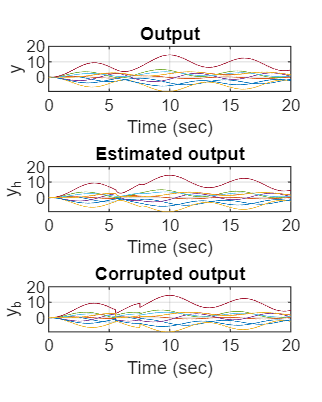

%output
subplot(3,1,1);
plot(t, output);
grid on;
title('Output');
xlabel('Time (sec)');
ylabel('y');
%ylim([-70,70]);

%estimated output
subplot(3,1,2);
plot(t, estimated_output);
grid on;
title('Estimated output');
xlabel('Time (sec)');
ylabel('y_h');
%ylim([-70,70]);

%corrupted output
subplot(3,1,3);
plot(t, corrupted_output);
grid on;
title('Corrupted output');
xlabel('Time (sec)');
ylabel('y_b');

figureWidth = 800;
figureHeight = 1000; 
set(gcf, 'Position', [100, 100, figureWidth, figureHeight]);

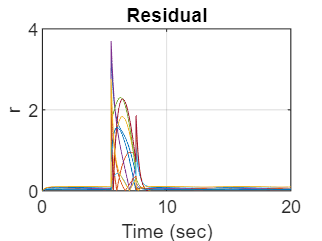


%residual
figure;
plot(t, residual);
grid on;
title('Residual');
xlabel('Time (sec)');
ylabel('r');

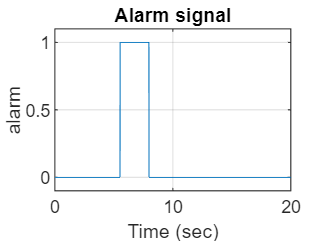

%ylim([0,1]);

%alarm signal
figure
plot(t, alarm);
grid on;
title('Alarm signal');
xlabel('Time (sec)');
ylabel('alarm');
ylim([-0.1,1.1]);